# Gappy experiments

## PDE Settings

### Spatial Dimensionality

Nx = 1000;

### Diffusion

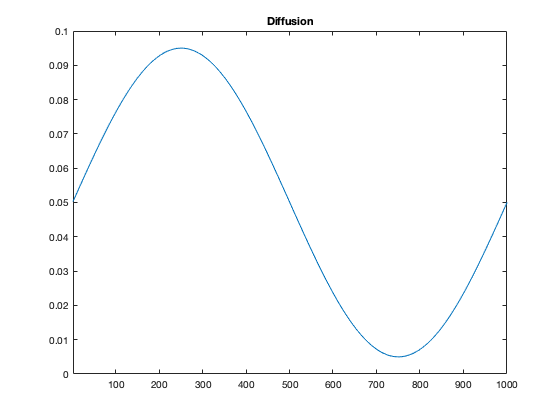

k =0; 
D  = genDiffusion(Nx,0.9,1,0.5e-1, @(u) [1+u^2*k,2*u*k]);

plot(axes(figure),1:(Nx+1),D.val); title('Diffusion');
xlim([1,Nx+1]);

### Initial and Boundary Conditions

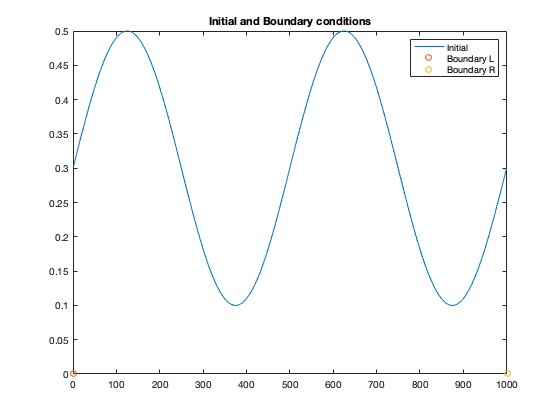

bc = genBC(1,[0,0]);
x0 = genInit(Nx,0.2,2,0.3);

plot(axes(figure),1:Nx,x0,'-',0,bc.val(1),'o',Nx+1,bc.val(2),'o');
title('Initial and Boundary conditions');
xlim([0,Nx+1]); legend({'Initial','Boundary L','Boundary R'});

### Problem Constructors

makeFOM = @(q,name) genProblem(name,Nx,genParam(D,bc,q),x0);
makeROM_I = @(name,q,encoder) genProblem(name,Nx,genParam(D,bc,q),x0,encoder);
makeROM_II = @(name,q,encoder,nfa) genProblem(name,Nx,genParam(D,bc,q),x0,encoder,nfa.res,nfa.jac);

### Temporal Dimensionality

T = 1;
Nt = 100;
dt = T/Nt;

## Nonlinear Solver Settings

newton_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 0,...
    'tol_rel'  , 1e-4,...
    'tol_g'    , 0,...
    'tol_rel_g', 0 ...
    );

nlin_newton = @(x,Res,Jac) newton(x,Res,Jac,newton_param);

## FOM

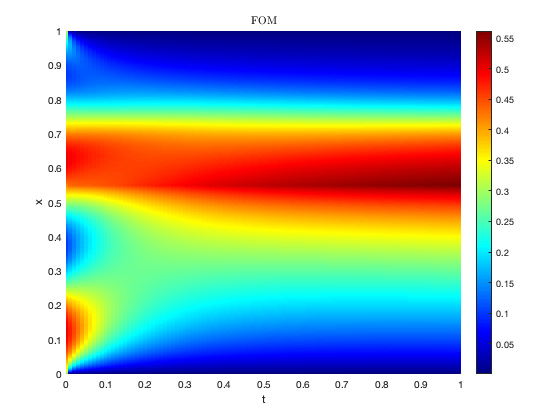

q = genSource(Nx,0.55,1e+2);
FOM = solveDif(T,Nt,makeFOM(q,'FOM'),nlin_newton);

plotSol(axes(figure),FOM);


[X,W,Jw,Y] = collectSolData(FOM);
Q = repmat(q.val,1,Nt+1);
Q = [Q;zeros(size(Y))];